# Show  Diagram FP demo

Use ShowDiagramFP function to show the Fuel-Product diagram.

### **Read Data Model**

file = "C:\Users\ctorr\Documents\Proyectos\TaesLab\Examples\cgam\cgam_model.json";
data = ReadDataModel(file);

### **Build Diagram FP**

Get the DiagramFP results info and save it into a file

res=DiagramFP(data,'SaveAs','DiagramFP.xlsx');

INFO: cMessageLogger. Diagram FP is saved in file DiagramFP.xlsx


### Plot Diagram FP

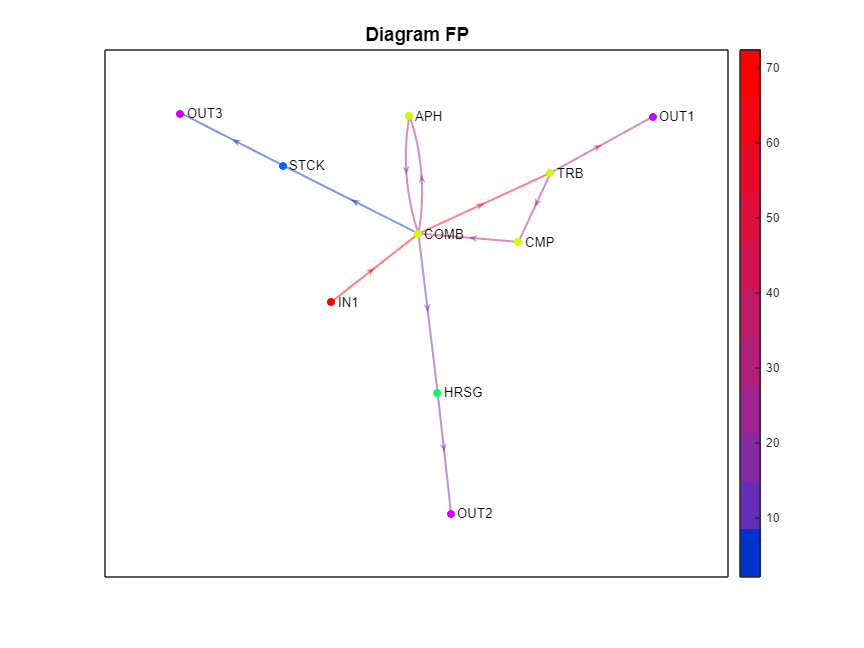

ShowGraph(res,'Graph',cType.Tables.DIGRAPH_FP);

ShowResults(res,'Table',cType.Tables.TABLE_FP);


FP Table (MW) - REF

 Key            COMB        CMP        TRB        APH       HRSG       STCK        ENV      Total
——————————————————————————————————————————————————————————————————————————————————————————————————
 COMB          0.000      0.000     63.720     24.026     12.662      2.122      0.000    102.530
 CMP          28.651      0.000      0.000      0.000      0.000      0.000      0.000     28.651
 TRB           0.000     31.105      0.000      0.000      0.000      0.000     30.000     61.105
 APH          21.688      0.000      0.000      0.000      0.000      0.000      0.000     21.688
 HRSG          0.000      0.000      0.000      0.000      0.000      0.000      9.303      9.303
 STCK          0.000      0.000      0.000      0.000      0.000      0.000      2.122      2.122
 ENV          72.465      0.000      0.000      0.000      0.000      0.000      0.000     72.465
———————————————————————————————————————————————————————————————————————————————————————————————

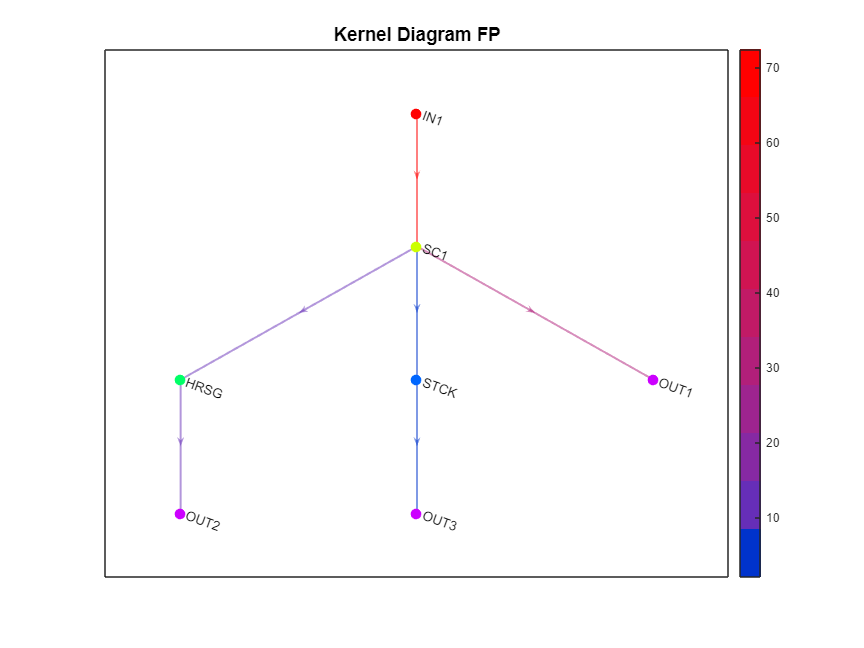

ShowGraph(res,'Graph',cType.Tables.KDIGRAPH_FP);

ShowResults(res,'Table',cType.Tables.KTABLE_FP);


Kernel FP Table (MW) - REF

 Key             SC1       HRSG       STCK        ENV      Total
—————————————————————————————————————————————————————————————————
 SC1           0.000     12.662      2.122     30.000     44.784
 HRSG          0.000      0.000      0.000      9.303      9.303
 STCK          0.000      0.000      0.000      2.122      2.122
 ENV          72.465      0.000      0.000      0.000     72.465
—————————————————————————————————————————————————————————————————
 Total        72.465     12.662      2.122     41.425           



ShowResults(res,'Table',cType.Tables.PROCESS_GROUP)


Graph Components - REF

Key   Group  
——————————————
IN1   IN     
COMB  SC1    
CMP   SC1    
TRB   SC1    
APH   SC1    
HRSG  HRSG   
STCK  STCK   
OUT1  OUT    
OUT2  OUT    
OUT3  OUT    



### Plot Cost Table FP

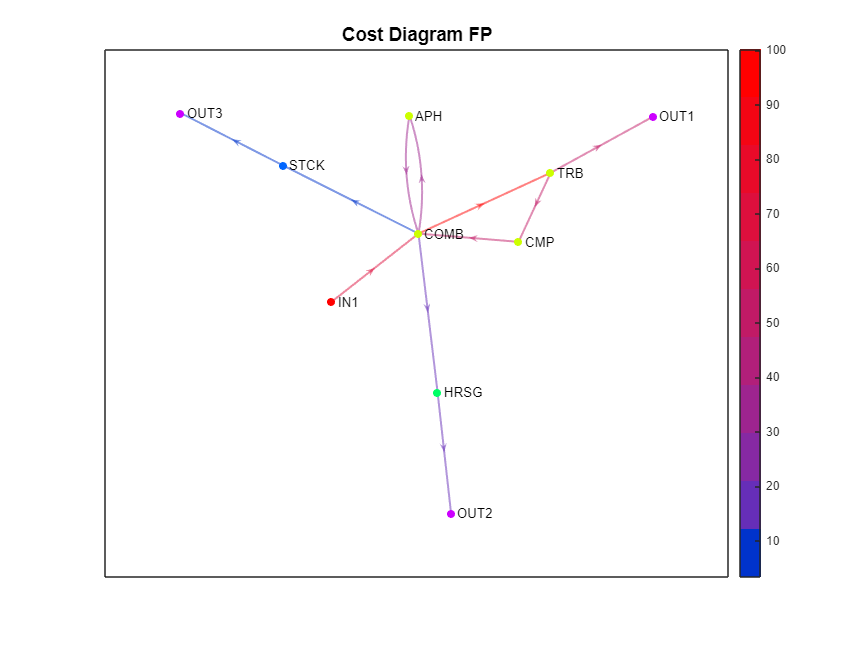

ShowGraph(res,'Graph',cType.Tables.DIGRAPH_COST_FP);

ShowResults(res,'Table',cType.Tables.COST_TABLE_FP);


FP Exergy Cost Table (MW) - REF

 Key            COMB        CMP        TRB        APH       HRSG       STCK        ENV      Total
——————————————————————————————————————————————————————————————————————————————————————————————————
 COMB          0.000      0.000    100.232     37.793     19.917      3.338      0.000    161.280
 CMP          51.022      0.000      0.000      0.000      0.000      0.000      0.000     51.022
 TRB           0.000     51.022      0.000      0.000      0.000      0.000     49.210    100.232
 APH          37.793      0.000      0.000      0.000      0.000      0.000      0.000     37.793
 HRSG          0.000      0.000      0.000      0.000      0.000      0.000     19.917     19.917
 STCK          0.000      0.000      0.000      0.000      0.000      0.000      3.338      3.338
 ENV          72.465      0.000      0.000      0.000      0.000      0.000      0.000     72.465
———————————————————————————————————————————————————————————————————————————————————

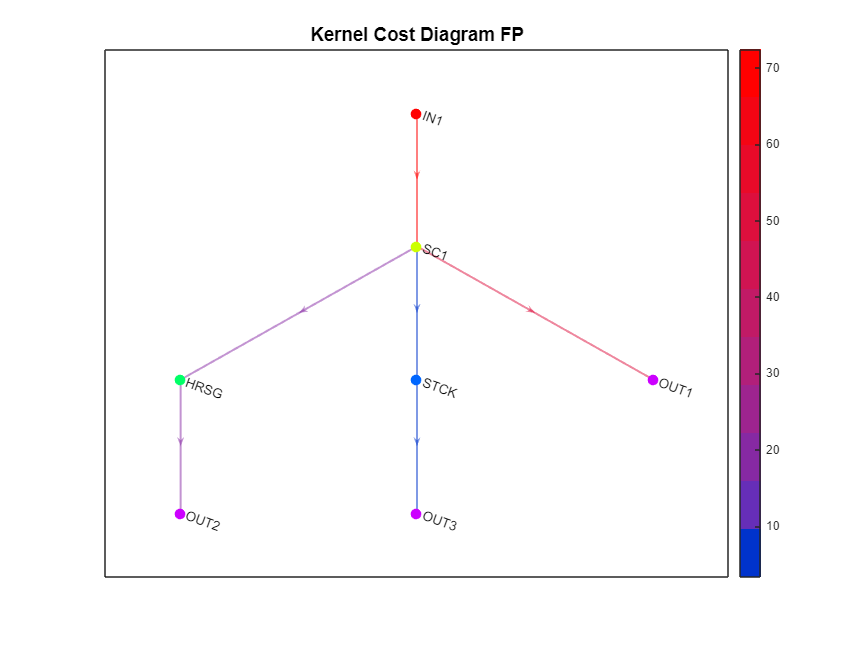

ShowGraph(res,'Graph',cType.Tables.KDIGRAPH_COST_FP);

ShowResults(res,'Table',cType.Tables.KTABLE_COST_FP);


Kernel FP Exergy Cost Table (MW) - REF

 Key             SC1       HRSG       STCK        ENV      Total
—————————————————————————————————————————————————————————————————
 SC1           0.000     19.917      3.338     49.210     72.465
 HRSG          0.000      0.000      0.000     19.917     19.917
 STCK          0.000      0.000      0.000      3.338      3.338
 ENV          72.465      0.000      0.000      0.000     72.465
—————————————————————————————————————————————————————————————————
 Total        72.465     19.917      3.338     72.465           



### Additional Help Information

help DiagramFP

 DiagramFP - Get the FP diagrams for a plant state.
    These diagrams can be represented graphically using the ShowGraph function, 
    or using external graphics software such as yEd, saving the adjacency tables
    of the graph in xlsx format.
   	
    Syntax
      res = DiagramFP(data,Name,Value);
 
    Input Arguments
      data - cReadModel Object containing the data model information.
 
    Name-Value Arguments
      State - Indicate one valid state to get exergy values. 
        char array
      Show -  Show results on console
        true | false (default)
      SaveAs - Name of the file where the results are saved.
        char array | string
 
    Output Arguments
      res - cResultInfo object contains the FP diagram tables
       The following tables are obtained:
        atfp  - Diagram FP adjacency table                                     
        atcfp - Cost Diagram FP adjacency table
        ktfp  - Kernel Diagram FP adjacency table
